load sampleEEGdata.mat

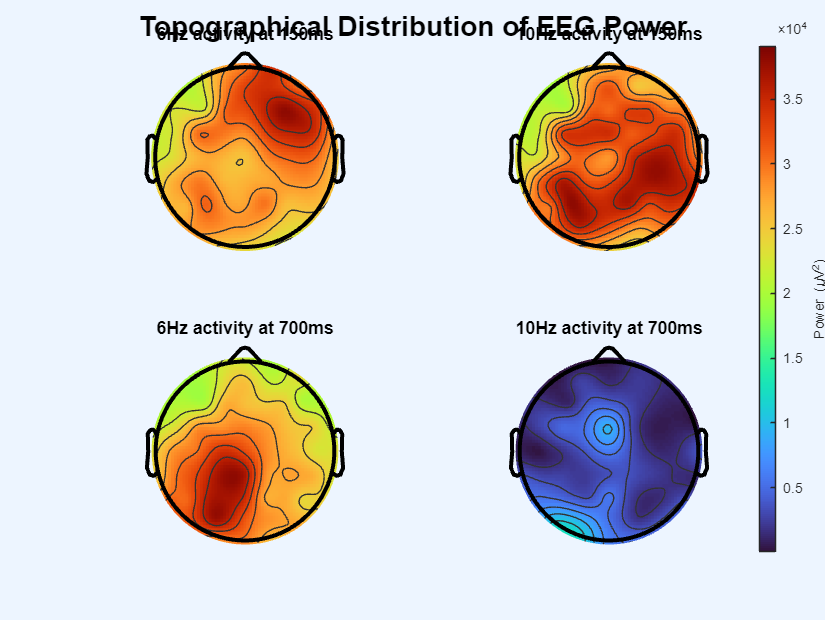

t_window_hwidth = 200; %% The window is 400ms long. Which is around 3*(1/(6Hz))*1000
time = [150, 700];
power = zeros([EEG.nbchan,2,2]); %% No. of Electrodes x No. of Freq x No. of Time2Check

for ti = 1:length(time)
    
    t_window_id = find(EEG.times >= time(ti) - t_window_hwidth,1):find(EEG.times <= time(ti) + t_window_hwidth, 1, "last");
    t_window = EEG.times(t_window_id);
    t_window_width = length(t_window);
    
    for e = 1:EEG.nbchan
        signal = squeeze(EEG.data(e,:,1));
        signal = detrend(signal);
        
        w_signal = signal(t_window_id);
        hann_window = hann(t_window_width);
        
        wh_signal = w_signal.*hann_window';
        
        fft_whs = fft(wh_signal);
        freq = (0:t_window_width-1)*(EEG.srate/t_window_width);
        power(e,1,ti) = abs(fft_whs(find(freq <= 6, 1, "last"))).^2;
        power(e,2,ti) = abs(fft_whs(find(freq <= 10, 1, "last"))).^2;
    end
end

figure;
subplot(221)
topoplot(squeeze(power(:,1,1)), EEG.chanlocs,'electrodes', 'off', 'plotrad', .53);
title("6Hz activity at 150ms")
subplot(222)
topoplot(squeeze(power(:,2,1)), EEG.chanlocs,'electrodes', 'off', 'plotrad', .53);
title("10Hz activity at 150ms")
subplot(223)
topoplot(squeeze(power(:,1,2)), EEG.chanlocs,'electrodes', 'off', 'plotrad', .53);
title("6Hz activity at 700ms")
subplot(224);
topoplot(squeeze(power(:,2,2)), EEG.chanlocs,'electrodes', 'off', 'plotrad', .53);
title("10Hz activity at 700ms")


clim = [min(power(:)), max(power(:))];
caxis(clim)
cb = colorbar('Position', [0.92 0.11 0.02 0.815]); 
ylabel(cb, 'Power (\muV^2)'); 
sgtitle('Topographical Distribution of EEG Power', 'FontSize', 14, 'FontWeight', 'bold');

P = [1 2 1; 2 2 3; 1 3 1]

P =      1     2     1
     2     2     3
     1     3     1


Q = [0 3 4;-3 0 1;-4 -1 0]

Q =      0     3     4
    -3     0     1
    -4    -1     0



Q*P - P*Q

ans =     20    16     7
    16    -6   -12
     7   -12   -14
